## Load data and nets

clear
currentFolder = fileparts(matlab.desktop.editor.getActiveFilename);
addpath(fullfile(currentFolder, '..', 'src'));
dataFolder = fullfile(currentFolder, '..', 'data');
modelBaseDir = fullfile(currentFolder, '..', 'models', 'LSTM');

zoneIds = [8, 9, 10, 11];
zoneNames = ["Anagnina", "Trieste", "Della Vittoria", "Tor di Quinto"];
windowSize = 48;
targetName = "AAC_energy";

numZones = numel(zoneIds);
zoneDataList = cell(numZones, 1);
zoneSplitList = cell(numZones, 1);
modelsList = cell(numZones, 1);

for i = 1:numZones
    zId = zoneIds(i);
    zoneData = loadZoneData(dataFolder, zId);

    hours = hour(zoneData.datetime) + minute(zoneData.datetime)/60;
    zoneData.cosHour = cos(2 * pi * hours / 24);
    zoneData.sinHour = sin(2 * pi * hours / 24);

    zoneDir = fullfile(modelBaseDir, sprintf("Zone%d", zId));
    matFiles = dir(fullfile(zoneDir, "LSTM_Zone*.mat"));
    if isempty(matFiles)
        error("Model file not found for Zone %d in directory %s", zId, zoneDir);
    end

    rmseValues = zeros(numel(matFiles), 1);
    for f = 1:numel(matFiles)
        tokens = regexp(matFiles(f).name, 'RMSE([\d.]+)', 'tokens', 'once');
        if ~isempty(tokens)
            rmseValues(f) = str2double(tokens{1});
        else
            rmseValues(f) = Inf;
        end
    end
    [~, bestIdx] = min(rmseValues);

    modelData = load(fullfile(zoneDir, matFiles(bestIdx).name));
    modelsList{i} = modelData;

    [~, ~, testData, ~] = splitZoneData(zoneData, windowSize, modelData.predictorNames, targetName);
    zoneDataList{i} = zoneData;
    zoneSplitList{i} = testData;
end

Zone "Zone_1016_Anagnina" loaded: 2784 rows (58 complete days, 48 steps/day).
Day breakdown: 41 working days (mean: 252.0 kWh), 17 non-working days (mean: 148.9 kWh).
Seasonal clusters identified (4 clusters):
  Cluster 1: 2023-02-15 (Wed) to 2023-02-28 (Tue) (14 days)
  Cluster 2: 2023-05-31 (Wed) to 2023-06-15 (Thu) (16 days)
  Cluster 3: 2023-07-12 (Wed) to 2023-07-25 (Tue) (14 days)
  Cluster 4: 2023-09-27 (Wed) to 2023-10-10 (Tue) (14 days)


Split completed: 1824 train, 384 val, 384 test samples.


Zone "Zone_214_Trieste" loaded: 2784 rows (58 complete days, 48 steps/day).
Day breakdown: 41 working days (mean: 136.9 kWh), 17 non-working days (mean: 94.8 kWh).
Seasonal clusters identified (4 clusters):
  Cluster 1: 2023-02-15 (Wed) to 2023-02-28 (Tue) (14 days)
  Cluster 2: 2023-05-31 (Wed) to 2023-06-15 (Thu) (16 days)
  Cluster 3: 2023-07-12 (Wed) to 2023-07-25 (Tue) (14 days)
  Cluster 4: 2023-09-27 (Wed) to 2023-10-10 (Tue) (14 days)


Split completed: 1824 train, 384 val, 384 test samples.


Zone "Zone_2004_Della Vittoria,Tomba di Nerone,Tor di Quinto2" loaded: 2784 rows (58 complete days, 48 steps/day).
Day breakdown: 41 working days (mean: 156.9 kWh), 17 non-working days (mean: 114.6 kWh).
Seasonal clusters identified (4 clusters):
  Cluster 1: 2023-02-15 (Wed) to 2023-02-28 (Tue) (14 days)
  Cluster 2: 2023-05-31 (Wed) to 2023-06-15 (Thu) (16 days)
  Cluster 3: 2023-07-12 (Wed) to 2023-07-25 (Tue) (14 days)
  Cluster 4: 2023-09-27 (Wed) to 2023-10-10 (Tue) (14 days)


Split completed: 1824 train, 384 val, 384 test samples.


Zone "Zone2002_Tor di Quinto6" loaded: 2784 rows (58 complete days, 48 steps/day).
Day breakdown: 41 working days (mean: 303.0 kWh), 17 non-working days (mean: 228.9 kWh).
Seasonal clusters identified (4 clusters):
  Cluster 1: 2023-02-15 (Wed) to 2023-02-28 (Tue) (14 days)
  Cluster 2: 2023-05-31 (Wed) to 2023-06-15 (Thu) (16 days)
  Cluster 3: 2023-07-12 (Wed) to 2023-07-25 (Tue) (14 days)
  Cluster 4: 2023-09-27 (Wed) to 2023-10-10 (Tue) (14 days)


Split completed: 1824 train, 384 val, 384 test samples.


## Cross-zone evaluation (Zero-shot vs Scale-adapted)

zeroShotRMSE = zeros(numZones, numZones);
scaleAdaptedRMSE = zeros(numZones, numZones);

for src = 1:numZones
    net = modelsList{src}.LSTMnet;
    srcNorm = modelsList{src}.normParams;

    for tgt = 1:numZones
        tgtTest = zoneSplitList{tgt};
        tgtMean = modelsList{tgt}.normParams.muTarget;
        tgtStd = modelsList{tgt}.normParams.sigmaTarget;

        tgtXRaw = cell(numel(tgtTest.X), 1);
        for k = 1:numel(tgtTest.X)
            tgtXRaw{k} = tgtTest.X{k} .* modelsList{tgt}.normParams.sigma + modelsList{tgt}.normParams.mu;
        end

        tgtX_srcNorm = cell(numel(tgtTest.X), 1);
        for k = 1:numel(tgtTest.X)
            tgtX_srcNorm{k} = (tgtXRaw{k} - srcNorm.mu) ./ srcNorm.sigma;
        end

        yNorm = minibatchpredict(net, tgtX_srcNorm, SequencePaddingDirection="left");

        tReal = tgtTest.T .* modelsList{tgt}.normParams.sigmaTarget + modelsList{tgt}.normParams.muTarget;

        yZeroShot = yNorm .* srcNorm.sigmaTarget + srcNorm.muTarget;
        zeroShotRMSE(src, tgt) = rmse(yZeroShot, tReal);

        yScaleAdapted = yNorm .* tgtStd + tgtMean;
        scaleAdaptedRMSE(src, tgt) = rmse(yScaleAdapted, tReal);
    end
end

## Heatmaps and ASHRAE benchmark matrix

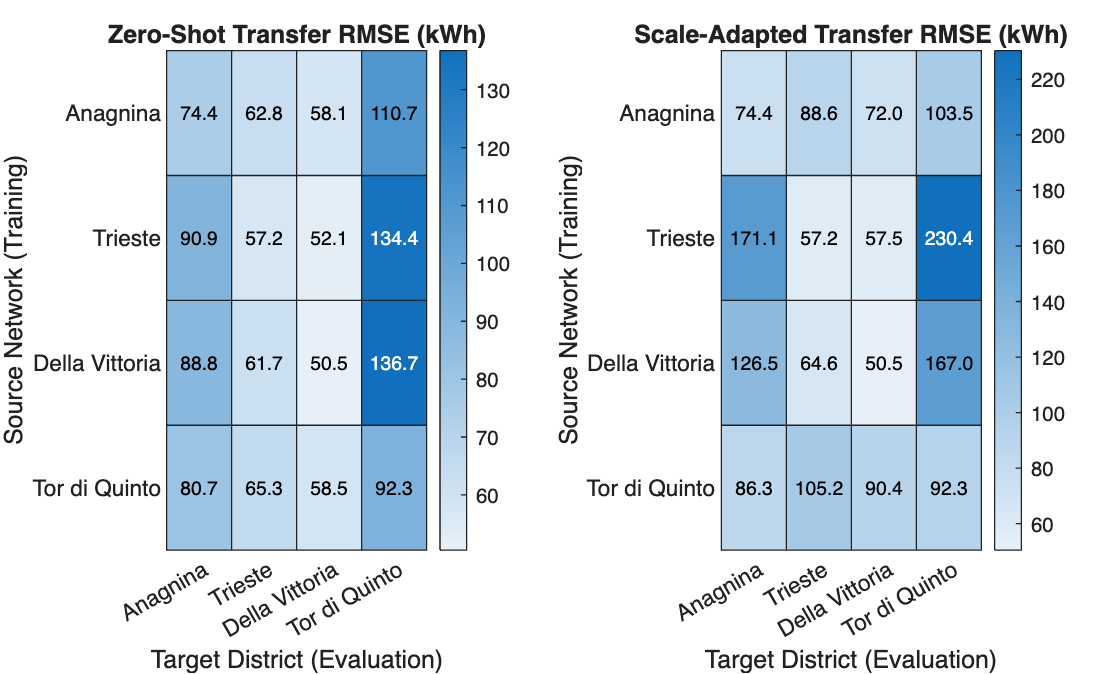

figure
tiledlayout(1, 2, Padding="compact", TileSpacing="compact")

nexttile
heatmap(zoneNames, zoneNames, zeroShotRMSE, CellLabelFormat="%.1f")
title("Zero-Shot Transfer RMSE (kWh)")
xlabel("Target District (Evaluation)")
ylabel("Source Network (Training)")

nexttile
heatmap(zoneNames, zoneNames, scaleAdaptedRMSE, CellLabelFormat="%.1f")
title("Scale-Adapted Transfer RMSE (kWh)")
xlabel("Target District (Evaluation)")
ylabel("Source Network (Training)")

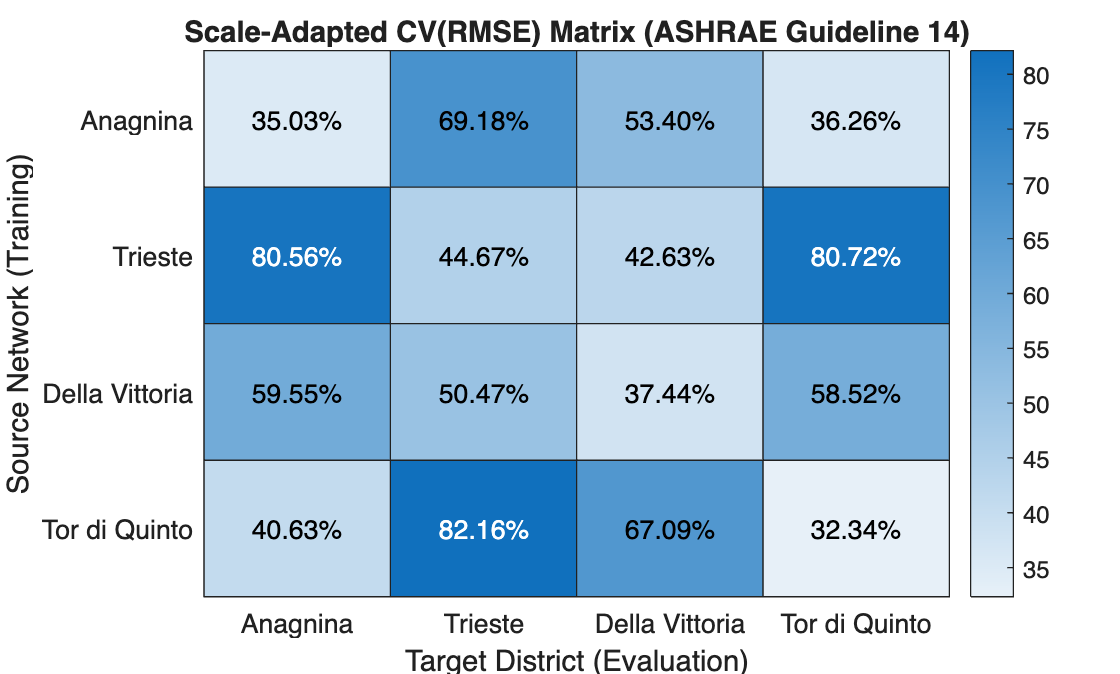

meanTargets = zeros(1, numZones);
for tgt = 1:numZones
    tReal = zoneSplitList{tgt}.T .* modelsList{tgt}.normParams.sigmaTarget + modelsList{tgt}.normParams.muTarget;
    meanTargets(tgt) = mean(tReal);
end

scaleAdaptedCV = (scaleAdaptedRMSE ./ meanTargets) * 100;

figure
heatmap(zoneNames, zoneNames, scaleAdaptedCV, CellLabelFormat="%.2f%%")
title("Scale-Adapted CV(RMSE) Matrix (ASHRAE Guideline 14)")
xlabel("Target District (Evaluation)")
ylabel("Source Network (Training)")

## Visual overlay (Measured vs Native vs Transferred)

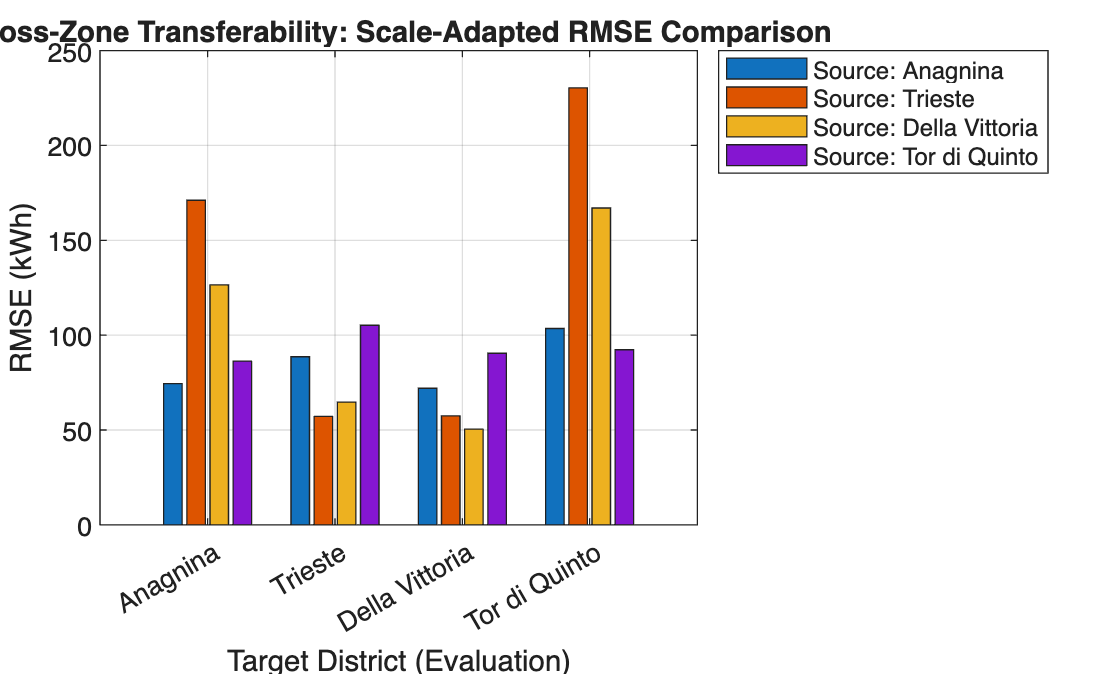

%% Section 4: Comprehensive Multi-Zone Visual Evaluation

% Grouped bar chart comparing native vs transferred performance across all 16 pairs
figure
bar(categorical(zoneNames, zoneNames), scaleAdaptedRMSE')
title("Cross-Zone Transferability: Scale-Adapted RMSE Comparison")
xlabel("Target District (Evaluation)")
ylabel("RMSE (kWh)")
legend(cellstr("Source: " + zoneNames), Location="northeastoutside")
grid on

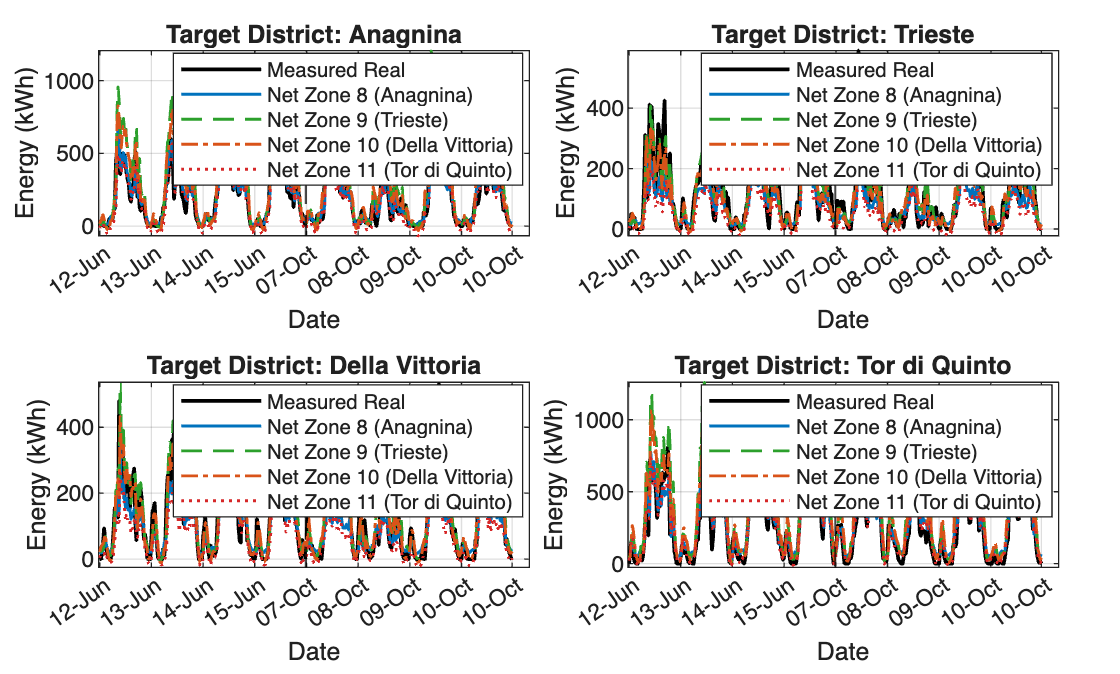


 Performance Log: Target District = Anagnina 


       Trained_On       RMSE_kWh    MAE_kWh    CV_RMSE_pct    Gap_vs_Native_pct
    ________________    ________    _______    ___________    _________________

    "Anagnina"             74.4      50.41        35.03                0       
    "Trieste"             171.1     122.95        80.56              130       
    "Della Vittoria"     126.48      91.37        59.55               70       
    "Tor di Quinto"       86.29      62.45        40.63               16       




 Performance Log: Target District = Trieste 


       Trained_On       RMSE_kWh    MAE_kWh    CV_RMSE_pct    Gap_vs_Native_pct
    ________________    ________    _______    ___________    _________________

    "Anagnina"            88.61      59.89        69.18             54.9       
    "Trieste"             57.21      39.57        44.67                0       
    "Della Vittoria"      64.64         43        50.47               13       
    "Tor di Quinto"      105.22      74.93        82.16             83.9       




 Performance Log: Target District = Della Vittoria 


       Trained_On       RMSE_kWh    MAE_kWh    CV_RMSE_pct    Gap_vs_Native_pct
    ________________    ________    _______    ___________    _________________

    "Anagnina"           71.99       51.39         53.4             42.7       
    "Trieste"            57.46       41.86        42.63             13.9       
    "Della Vittoria"     50.46          36        37.44                0       
    "Tor di Quinto"      90.44          66        67.09             79.2       




 Performance Log: Target District = Tor di Quinto 


       Trained_On       RMSE_kWh    MAE_kWh    CV_RMSE_pct    Gap_vs_Native_pct
    ________________    ________    _______    ___________    _________________

    "Anagnina"           103.48       81.7        36.26              12.1      
    "Trieste"            230.36      176.2        80.72             149.6      
    "Della Vittoria"     167.02      128.2        58.52                81      
    "Tor di Quinto"       92.29      66.22        32.34                 0      



%% Multi-Zone Evaluation: 4 Networks vs Ground Truth with Performance Log

figure
tiledlayout(2, 2, Padding="compact", TileSpacing="compact")

modelStyles = ["-", "--", "-.", ":"];
modelColors = ["#0072BD", "#2CA02C", "#D95319", "#D62728"];

for tgt = 1:numZones
    nexttile

    tgtTest = zoneSplitList{tgt};
    tReal = tgtTest.T .* modelsList{tgt}.normParams.sigmaTarget + modelsList{tgt}.normParams.muTarget;

    tgtXRaw = cell(numel(tgtTest.X), 1);
    for k = 1:numel(tgtTest.X)
        tgtXRaw{k} = tgtTest.X{k} .* modelsList{tgt}.normParams.sigma + modelsList{tgt}.normParams.mu;
    end

    yPredAll = cell(numZones, 1);
    rmseLog = zeros(numZones, 1);
    maeLog = zeros(numZones, 1);

    for src = 1:numZones
        srcNorm = modelsList{src}.normParams;
        tgtX_srcNorm = cell(numel(tgtTest.X), 1);
        for k = 1:numel(tgtTest.X)
            tgtX_srcNorm{k} = (tgtXRaw{k} - srcNorm.mu) ./ srcNorm.sigma;
        end

        yNorm = minibatchpredict(modelsList{src}.LSTMnet, tgtX_srcNorm, SequencePaddingDirection="left");
        yPred = yNorm .* modelsList{tgt}.normParams.sigmaTarget + modelsList{tgt}.normParams.muTarget;

        yPredAll{src} = yPred;
        rmseLog(src) = rmse(yPred, tReal);
        maeLog(src) = mean(abs(yPred - tReal));
    end

    cvLog = (rmseLog / mean(tReal)) * 100;
    gapLog = (rmseLog - rmseLog(tgt)) ./ rmseLog(tgt) * 100;

    % Eliminate calendar gap for visualization
    gapIdx = find(diff(tgtTest.timestamps) > minutes(30), 1);
    xVec = 1:numel(tReal);

    if ~isempty(gapIdx)
        xPlot = [xVec(1:gapIdx), gapIdx + 0.5, xVec(gapIdx+1:end)];
        tPlot = [tReal(1:gapIdx); NaN; tReal(gapIdx+1:end)];
    else
        xPlot = xVec;
        tPlot = tReal;
    end

    plot(xPlot, tPlot, "k-", LineWidth=1.4)
    hold on

    for s = 1:numZones
        yP = yPredAll{s};
        if ~isempty(gapIdx)
            yPlotS = [yP(1:gapIdx); NaN; yP(gapIdx+1:end)];
        else
            yPlotS = yP;
        end
        plot(xPlot, yPlotS, "LineStyle", modelStyles(s), "Color", modelColors(s), LineWidth=1.1)
    end

    if ~isempty(gapIdx)
        xline(gapIdx + 0.5, "k--", LineWidth=0.8)
    end

    tickIdx = [1:48:numel(tReal), numel(tReal)];
    xticks(tickIdx)
    xticklabels(string(tgtTest.timestamps(tickIdx), "dd-MMM"))
    xtickangle(35)
    hold off

    title(sprintf("Target District: %s", zoneNames(tgt)))
    xlabel("Date")
    ylabel("Energy (kWh)")
    legend(["Measured Real", "Net Zone 8 (Anagnina)", "Net Zone 9 (Trieste)", ...
        "Net Zone 10 (Della Vittoria)", "Net Zone 11 (Tor di Quinto)"], Location="best")
    grid on

    % Print structured performance log table for this district
    fprintf("\n Performance Log: Target District = %s \n", zoneNames(tgt));
    logTable = table(zoneNames', round(rmseLog, 2), round(maeLog, 2), round(cvLog, 2), round(gapLog, 1), ...
        VariableNames=["Trained_On", "RMSE_kWh", "MAE_kWh", "CV_RMSE_pct", "Gap_vs_Native_pct"]);
    disp(logTable);
end